% difference equation 
% sum(ak*y(n-k))=sum(bm*x(n-m))
%check the system stability by two method
% 1.impulse function must be absolute summable
% 2.Magintude of a polynomial function roots must be less than zero 

%y(n-k)/x(n-m)=bm/an


tic %start timer
b=[1]

b = 1

a=[1 -1 0.9]

a =     1.0000   -1.0000    0.9000


n=-20:100

n =    -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29


[h]=(impz(b,a,n))'

h =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000    1.0000    0.1000   -0.8000   -0.8900   -0.1700    0.6310    0.7840    0.2161   -0.4895   -0.6840   -0.2434    0.3722    0.5912    0.2563   -0.2758   -0.5065   -0.2583    0.1976    0.4300    0.2522   -0.1348   -0.3618   -0.2405    0.0852    0.3016    0.2249   -0.0465   -0.2489   -0.2071


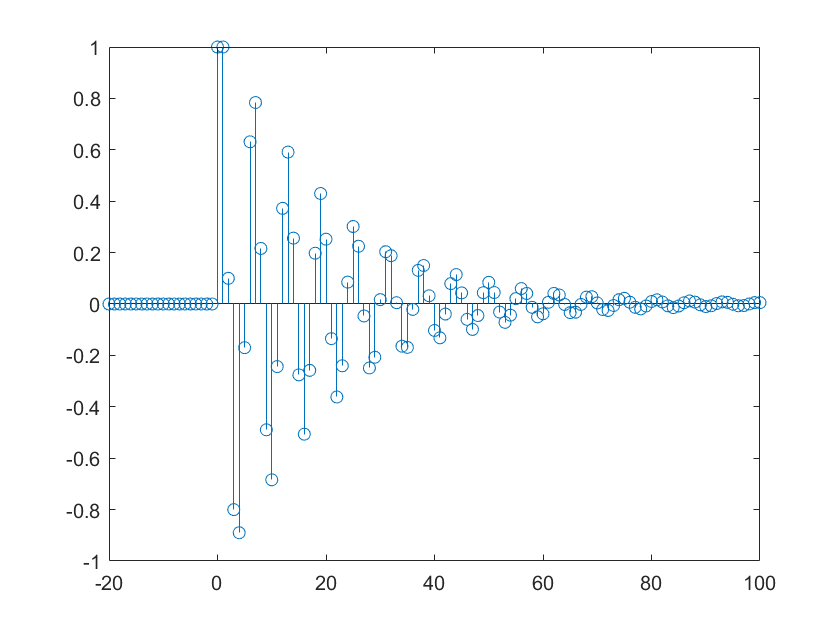

stem(n,h)

h=sum(abs(h))

h = 14.8337

z=roots(a) %find the roots of polynomial function

z =    0.5000 + 0.8062i
   0.5000 - 0.8062i


magz=abs(z) %find the magnitude

magz =     0.9487
    0.9487



toc %stop timer and show time

Elapsed time is 0.160948 seconds.



tic
[x,xn]=unitseq(-20,100,0)

x = 1×121 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


xn =    -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29


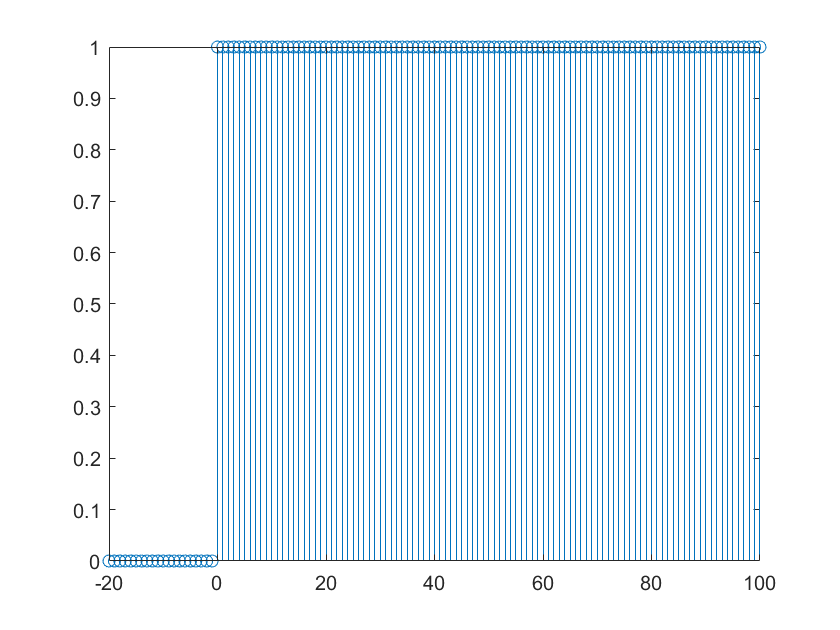

stem(xn,x)

s=filter(b,a,x)

s =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000    2.0000    2.1000    1.3000    0.4100    0.2400    0.8710    1.6550    1.8711    1.3816    0.6976    0.4542    0.8263    1.4176    1.6739    1.3981    0.8916    0.6333    0.8309    1.2609    1.5131    1.3783    1.0165    0.7760    0.8612    1.1628    1.3877    1.3412    1.0923    0.8852


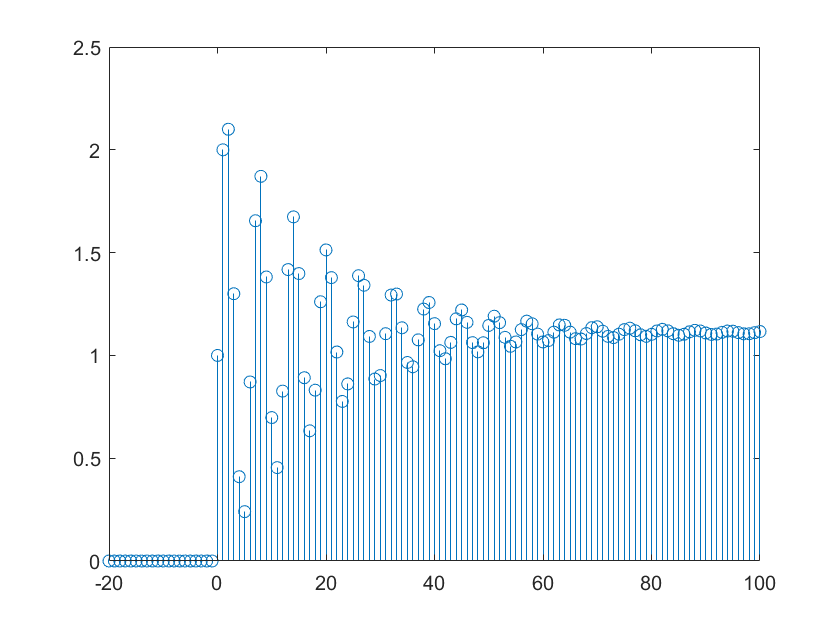

stem(xn,s)

toc

Elapsed time is 0.523069 seconds.
